Requirements for the data table:

- The data table is  MS Access

- **There is a field named "ID"**

clear;
clc;

Database Access connection ( [https://www.mathworks.com/help/database/ug/microsoft-access-odbc-windows.html](https://www.mathworks.com/help/database/ug/microsoft-access-odbc-windows.html)). 

Create a connection to the database: APPS -> Database Explorer-> Configure Datasourse -> **ODBS** datasourse->select the driver (depending on the type of table). Specify the name of the database **base_name **(we also call this database in the settings) . Specify the name of the table in the database **table_name **in the script:

path = 'C:\Users\and\OneDrive\Рабочий стол\CompAndGeosc\For_matlab.accdb'

path = 'C:\Users\and\OneDrive\Рабочий стол\CompAndGeosc\For_matlab.accdb'

base_name = 'For_matlab'

base_name = 'For_matlab'

table_name = '20210212_Tarko_Sale_Soil'

table_name = '20210212_Tarko_Sale_Soil'

Select the database and read the table:

conn = database(base_name,'','');
data = sqlread(conn,table_name);
data_for_map = sqlread(conn,table_name);

Set **n** (number of partition), **percent** (percent of the training subset), inputs and output for the network:

n = 100;
percent = 70;
inputs_for_network = {'WGS84East','WGS84North'};
output_for_network = 'TF024Cr_mg_kg';

The multilayer perceptron (MLP) with the Levenberg Marquart learning algorithm. Set  **maximum number of the neurons** in hidden layer and** number of the network trainings:**

max_num_neurons = 10;
number_of_train_network = 10;
iter = n*max_num_neurons*number_of_train_network;%число итераций для прогресс бара НЕ ТРОГАТЬ!

Create table *Partitions *with **ID** field (each repeats n times), **partition number **and **label for training **(**0**) or** test **(**1**) **subsets** . 

**The percentage of the training sample is exactly given, each point falls into the training subset a different number of times.**

column1 = 'ID';
column2 = 'Partitionnumber';
column3 = 'TrainingTest';
Train_marker = 0;
Test_marker = 1;


percent = n*percent/100;
initial_table_lenght = height(data);
final_table_lenght = initial_table_lenght*n;

a = 1;
b = 1;
c = n;
for d = b:c
    while a <= initial_table_lenght
        Partitions(b:c,column1) = data(a, column1);
        a = a + 1;
        b = c + 1;
        c = c + n;
    %else break    
    end
    
end
Partitions(:,column2) = table([zeros([final_table_lenght, 1])]);
b = 1;
c = n;
for d = b:c
    while c <= final_table_lenght
        Partitions(b:c,column2) = table((linspace(1,n,n))');
      
        b = c + 1;
        c = c + n;
    %else break    
    end
end
Partitions(:,column3) = table([zeros([final_table_lenght, 1])]);
Partitions = sortrows(Partitions,column2);
b = 1;
c = initial_table_lenght;
for d = b:c
    while c <= final_table_lenght
        Partitions(b:c,column3) = table((randperm(initial_table_lenght,initial_table_lenght))');
        b = c + 1;
        c = c + initial_table_lenght;
    end
end
Partitions2 = cell2mat(table2cell(Partitions(:, 3)));
for d = 1:final_table_lenght
    if Partitions2(d) <= (percent*initial_table_lenght)/n + 1 
        Partitions2(d) = Train_marker;
    else Partitions2(d) = Test_marker;
    end
end

Partitions2 = table(Partitions2);
Partitions(:,column3) = Partitions2;


Write the *Partitions* table to an Access database:

i = 1;
j = 0;
max_size = 65000;
out_table = 'Partitions';
j = max_size;
while max_size < final_table_lenght - i + 1
    sqlwrite(conn, out_table, Partitions(i:j,:));
    i = j + 1;
    j = i + max_size;
end
sqlwrite(conn, out_table, Partitions(i:end,:));

Clean Outlier Data. In the interactive window, select the input table, the column that you want to get rid of outliers. X-axis is default. 

If you do not need to get rid of outliers, just comment line 118 with a %.

lefttable = 'Partitions';
righttable = table_name;
Key = 'ID';


data = sqlinnerjoin(conn,lefttable,righttable,'Keys',Key);


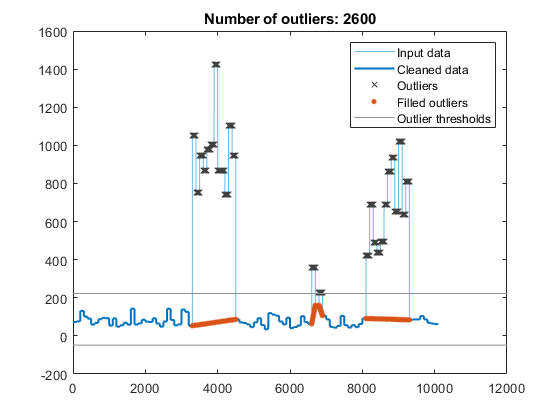

% Fill outliers
[cleanedData,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(data.TF024Cr_mg_kg,'linear');

% Visualize results
clf
plot(data.TF024Cr_mg_kg,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices),data.TF024Cr_mg_kg(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(find(outlierIndices),cleanedData(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices thresholdLow thresholdHigh
data.TF024Cr_mg_kg = cleanedData;

Сreate tables of training and test subsets for each partition and train the network on normalized data without outliers.

The data is normalized from 0 to 1.

We set the activation function **transfer_function** and the training algorithm **training_algorithm.**

**Activation functions:**

`compet - Competitive transfer function.`

`elliotsig - Elliot sigmoid transfer function.`

`hardlim - Positive hard limit transfer function.`

`hardlims - Symmetric hard limit transfer function.`

`logsig - Logarithmic sigmoid transfer function.`

`netinv - Inverse transfer function.`

`poslin - Positive linear transfer function.`

`purelin - Linear transfer function.`

`radbas - Radial basis transfer function.`

`radbasn - Radial basis normalized transfer function.`

`satlin - Positive saturating linear transfer function.`

`satlins - Symmetric saturating linear transfer function.`

`softmax - Soft max transfer function.`

`tansig - Symmetric sigmoid transfer function.`

`tribas - Triangular basis transfer function.`

**алгоритмы обучения - **[https://www.mathworks.com/help/deeplearning/ref/feedforwardnet.html?s_tid=doc_ta](https://www.mathworks.com/help/deeplearning/ref/feedforwardnet.html?s_tid=doc_ta)

This network architecture is designed for data with two inputs (spatial coordinates) and one output (element content). For other data configurations, you need to change the network architecture manually, or look for ready-made solutions.

transfer_function = 'logsig'

transfer_function = 'logsig'

training_algorithm ='trainlm' 

training_algorithm = 'trainlm'



tic
f = waitbar(0,'Training is processing');

j = 1;

result = struct( 'number_of_partition', [],...
    'number_of_neurons_hidden',[],...
    'train_number',[],'RMSE_test', [], ...
    'RMSE_train', [],'RMSE_all',[], 'net', []);

number_of_neurons = 1;

for number_of_partition = 1:n
rows = data.Partitionnumber == number_of_partition;
train_data = data(rows,:);
rows = train_data.TrainingTest == Train_marker;
train_data = train_data(rows,:);


rows = data.Partitionnumber == number_of_partition;
test_data = data(rows,:);
rows = test_data.TrainingTest == Test_marker;
test_data = test_data(rows,:);

%normalize train data
input_train_data = table2cell(train_data(:, inputs_for_network));
output_train_data = table2cell(train_data(:, output_for_network));


input_test_data = table2cell(test_data(:, inputs_for_network));
output_test_data = table2cell(test_data(:, output_for_network));

[input_train_data_normal,input_train_settings] = mapminmax(table2array(train_data(:, inputs_for_network))',0 , 1);
[output_train_data_normal, output_train_settings] = mapminmax(table2array(train_data(:, output_for_network))',0 , 1);

%normalize test data
[input_test_data_normal,input_test_settings] = mapminmax(table2array(test_data(:, inputs_for_network))',0 , 1);
[output_test_data_normal,output_test_settings] = mapminmax(table2array(test_data(:, output_for_network))',0 , 1);




for number_of_neurons = 1:max_num_neurons

    for i=1:number_of_train_network
      


net = feedforwardnet(number_of_neurons);
net.numinputs = 2;
net.inputConnect = [1 1; 0 0];
net.layers{1}.transferFcn = 'logsig';
net.layers{2}.transferFcn = transfer_function;
net.trainFcn = training_algorithm;

net.divideParam.trainRatio = 1.0; % training set [%]
net.divideParam.valRatio = 0.0; % validation set [%]
net.divideParam.testRatio = 0.0; % test set [%]
net = train(net, num2cell (input_train_data_normal), num2cell (output_train_data_normal));

% simulate a network over test range
Y_test = net(input_test_data_normal);
Y_test2 = mapminmax('reverse',Y_test,output_test_settings);
%the same is
%Y2 = sim(net, input_test_data');
%number_of_neurons = number_of_neurons;
RMSE_test = sqrt(mean((Y_test2 - cell2mat(output_test_data')).^2));


Y_train = net(input_train_data_normal);
Y_train2 = mapminmax('reverse',Y_train,output_train_settings);
RMSE_train = sqrt(mean((Y_train2 - cell2mat(output_train_data')).^2));

% simulate a network over all range
all_input_data = [input_train_data; input_test_data];
all_output_data = [output_train_data; output_test_data;];
[all_input_data_normal,input_all_settings] = mapminmax(cell2mat(all_input_data)',0 , 1);
[all_output_data_normal,output_all_settings] = mapminmax(cell2mat(all_output_data)', 0 , 1);

Y_all = net(all_input_data_normal);
Y_all2 = mapminmax('reverse',Y_all,output_all_settings);
RMSE_all = sqrt(mean((Y_all2 - cell2mat(all_output_data')).^2));


result(j) = struct( 'number_of_partition', number_of_partition,...
    'number_of_neurons_hidden',number_of_neurons, ...
    'train_number',i,'RMSE_test', RMSE_test, ...
    'RMSE_train', RMSE_train, 'RMSE_all',RMSE_all, 'net', net);


%i=i+1;
j=j+1;
waitbar(j/iter,f);
    end


end
number_of_neurons = number_of_neurons+1;


end

close(f);
toc

Elapsed time is 1432.742572 seconds.


Training without data normalization.

If you need to train the network without data normalization, select the entire code of the previous section and press Ctrl+R + select the entire code of this section and press Ctrl+T. Comment out is to select and Ctrl+R. Uncomment is to select and Ctrl+T.

% 
% transfer_function = 'logsig'
% training_algorithm 'trainlm' 
% 
% 
% 
% tic
% f = waitbar(0,'Training is processing');
% 
% j = 1;
% 
% result = struct( 'number_of_partition', [],...
%     'number_of_neurons_hidden',[],...
%     'train_number',[],'RMSE_test', [], ...
%     'RMSE_train', [],'RMSE_all',[], 'net', []);
% 
% number_of_neurons = 1;
% 
% for number_of_partition = 1:n
% rows = data.Partitionnumber == number_of_partition;
% train_data = data(rows,:);
% rows = train_data.TrainingTest == Train_marker;
% train_data = train_data(rows,:);
% 
% 
% rows = data.Partitionnumber == number_of_partition;
% test_data = data(rows,:);
% rows = test_data.TrainingTest == Test_marker;
% test_data = test_data(rows,:);
% 
% %normalize train data
% input_train_data = table2cell(train_data(:, inputs_for_network));
% output_train_data = table2cell(train_data(:, output_for_network));
% 
% 
% input_test_data = table2cell(test_data(:, inputs_for_network));
% output_test_data = table2cell(test_data(:, output_for_network));
% 
% [input_train_data_normal,input_train_settings] = mapminmax(table2array(train_data(:, inputs_for_network))',0 , 1);
% [output_train_data_normal, output_train_settings] = mapminmax(table2array(train_data(:, output_for_network))',0 , 1);
% 
% %normalize test data
% [input_test_data_normal,input_test_settings] = mapminmax(table2array(test_data(:, inputs_for_network))',0 , 1);
% [output_test_data_normal,output_test_settings] = mapminmax(table2array(test_data(:, output_for_network))',0 , 1);
% 
% 
% 
% 
% for number_of_neurons = 1:max_num_neurons
% 
%     for i=1:number_of_train_network
%       
% 
% 
% net = feedforwardnet(number_of_neurons);
% net.numinputs = 2;
% net.inputConnect = [1 1; 0 0];
% net.layers{1}.transferFcn = 'logsig';
% net.layers{2}.transferFcn = transfer_function;
% net.trainFcn = training_algorithm;
% 
% net.divideParam.trainRatio = 1.0; % training set [%]
% net.divideParam.valRatio = 0.0; % validation set [%]
% net.divideParam.testRatio = 0.0; % test set [%]
% net = train(net, (input_train_data'),(output_train_data'));
% 
% % simulate a network over test range
% Y_test = net(input_test_data');
% %Y_test2 = mapminmax('reverse',Y_test,output_test_settings);
% %the same is
% %Y2 = sim(net, input_test_data');
% %number_of_neurons = number_of_neurons;
% RMSE_test = sqrt(mean((cell2mat(Y_test) - cell2mat(output_test_data')).^2));
% 
% 
% Y_train = net(input_train_data');
% %Y_train2 = mapminmax('reverse',Y_train,output_train_settings);
% RMSE_train = sqrt(mean((cell2mat(Y_train) - cell2mat(output_train_data')).^2));
% 
% % simulate a network over all range
% all_input_data = [input_train_data; input_test_data];
% all_output_data = [output_train_data; output_test_data;];
% [all_input_data_normal,input_all_settings] = mapminmax(cell2mat(all_input_data)',0 , 1);
% [all_output_data_normal,output_all_settings] = mapminmax(cell2mat(all_output_data)', 0 , 1);
% 
% Y_all = net(all_input_data');
% %Y_all2 = mapminmax('reverse',Y_all,output_all_settings);
% RMSE_all = sqrt(mean((cell2mat(Y_all) - cell2mat(all_output_data')).^2));
% 
% 
% result(j) = struct( 'number_of_partition', number_of_partition,...
%     'number_of_neurons_hidden',number_of_neurons, ...
%     'train_number',i,'RMSE_test', RMSE_test, ...
%     'RMSE_train', RMSE_train, 'RMSE_all',RMSE_all, 'net', net);
% 
% 
% %i=i+1;
% j=j+1;
% waitbar(j/iter,f);
%     end
% 
% 
% end
% number_of_neurons = number_of_neurons+1;
% 
% 
% end
% 
% close(f);
% toc

Choosе the best neural networks (table **best_networks_partitions**)

k=1;
f=1

f = 1

for f = 1:n
DATA = result(arrayfun(@(x) all(x.number_of_partition == f),result));


% for m = 1:max_num_neurons
% DATA1 = DATA(arrayfun(@(x) all(x.number_of_neurons_hidden == m) , DATA))
[cnt,idx] = min([DATA.RMSE_all]);
best_networks_partitions(k) = DATA(idx);
k = k + 1;
% 
% 
% 
% end
DATA = struct([]);
end
%save('20210419_variables_Cr_Noyabrsk.mat'); %save all variables

Build histograms for RMSE_all, RMSE_test, RMSE_train. 

Create a **data_for_histogram** table. Build histograms for RMSE test, training and all. Histograms are built for each point. 

For the histogram, we take the error values of only those partitions in which this point participated as a training point.

Read here[https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)

Plot the probability density ('Normalization','pdf') and the width of each column = 0.5 ('BinWidth',0.5). These parameters can be changed (lines 380 for RMSE_all, 395 for RMSE_test, 410 for RMSE_train).

xlim and **ylim** can also change for each type of histogram

You can change **k** (this is the title of the histogram, now it is the point ID);  **k1** (this is the additional part of the title, now it is the name of the element being modeled, before it \ is an escape sign) and **savename** (the name of the picture  saved ). If we change  k, k1, savename in this section, we change them for each type of histograms RMSE_all, RMSE_test and RMSE_train.

var1 = [best_networks_partitions.number_of_partition]';
var2 = [best_networks_partitions.RMSE_all]';
var3 = [best_networks_partitions.RMSE_test]';
var4 = [best_networks_partitions.RMSE_train]';
best_networks_partitions1 = table(var1,var2,var3,var4);
best_networks_partitions1.Properties.VariableNames = {'Partitionnumber';'RMSE_all';'RMSE_test';'RMSE_train'};
data_for_histogram = table;
for number_of_partition = 1:n
rows  = Partitions.Partitionnumber == number_of_partition;
data_for_histogram2  = Partitions(rows,:);
rows = data_for_histogram2.TrainingTest == Train_marker;
data_for_histogram = [data_for_histogram; data_for_histogram2(rows,:)] ;
end
data_for_histogram = join(data_for_histogram,best_networks_partitions1, ...
    'Keys','Partitionnumber');

ID = table(findgroups(data_for_histogram.ID));
data_for_histogram = [data_for_histogram ID] %add column

data_for_histogram = 7100×7 table
                          ID                          Partitionnumber    TrainingTest    RMSE_all    RMSE_test    RMSE_train    Var1
    ______________________________________________    _______________    ____________    ________    _________    __________    ____

    {'20070927-20070930-YNAO-TarkoSale-Soil(001)'}           1                0           31.481      38.641        21.665        1 
    {'20070927-20070930-YNAO-TarkoSale-Soil(003)'}           1                0           31.481      38.641        21.665        3 
    {'20070927-20070930-YNAO-TarkoSale-Soil(004)'}           1                0           31.481      38.641        21.665        4 
    {'20070927-20070930-YNAO-TarkoSale-Soil(005)'}           1

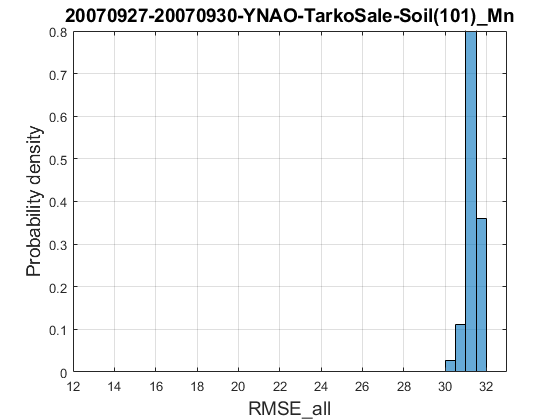


for point_number = 1:max (table2array (ID))
rows = data_for_histogram.Var1==point_number;
data_for_histogram_interim = data_for_histogram(rows,:);
h = histogram(data_for_histogram_interim.RMSE_all,'BinWidth',0.5, 'Normalization', 'pdf');
k = char(table2array( data_for_histogram_interim(1,'ID')));
k1 = strcat(k,'\_Mn');
grid on;
xlim([12, 33]);
ylim([0, 0.8]);
xlabel('RMSE\_all', 'FontSize', 14);
ylabel('Probability density', 'FontSize', 14);
title(k1,'FontSize', 14);
savename =strcat(k,'hist_RMSE_all_Mn') ;
saveas(h, savename, 'jpg');
end

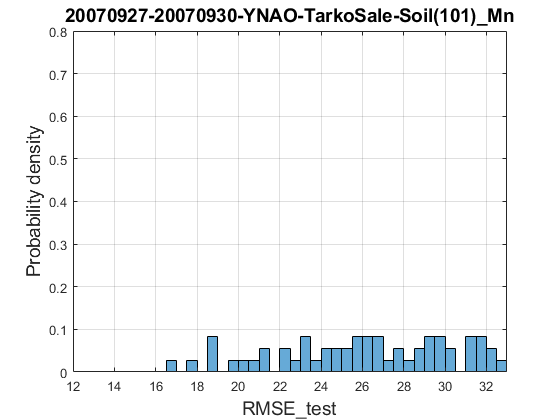

for point_number = 1:max (table2array (ID))
rows = data_for_histogram.Var1==point_number;
data_for_histogram_interim = data_for_histogram(rows,:);
h = histogram(data_for_histogram_interim.RMSE_test,'BinWidth',0.5,'Normalization','pdf');
k = char(table2array( data_for_histogram_interim(1,'ID')));
k1 = strcat(k,'\_Mn');
grid on;
xlim([12, 33]);
ylim([0, 0.8]);
xlabel('RMSE\_test', 'FontSize', 14);
ylabel('Probability density', 'FontSize', 14);
title(k1, 'FontSize', 14);
savename =strcat(k,'hist_RMSE_test_Mn') ;
saveas(h, savename, 'jpg');
end

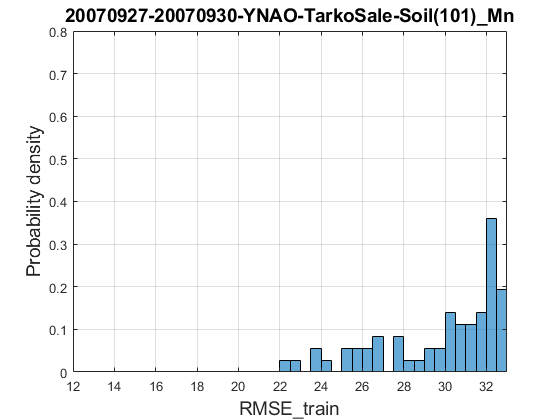

for point_number = 1:max (table2array (ID))
rows = data_for_histogram.Var1==point_number;
data_for_histogram_interim = data_for_histogram(rows,:);
h = histogram(data_for_histogram_interim.RMSE_train,'BinWidth',0.5,'Normalization', 'pdf');
k = char(table2array( data_for_histogram_interim(1,'ID')));
k1 = strcat(k,'\_Mn');
grid on;
xlim([12, 33]);
ylim([0, 0.8]);
xlabel('RMSE\_train', 'FontSize', 14);
ylabel('Probability density', 'FontSize', 14);
title(k1, 'FontSize', 14);
savename =strcat(k,'hist_RMSE_train_Mn') ;
saveas(h, savename, 'jpg');
end

Calculate SD, skewness, kurtosis (table statistics_data).

statistics_data = table;
for point_number = 1:max (table2array (ID))
rows = data_for_histogram.Var1==point_number;
statistics_data_interim = data_for_histogram(rows,:);

point_ID = statistics_data_interim.(1)(1);

mean_RMSE_all = mean(statistics_data_interim.RMSE_all);
mean_RMSE_test = mean(statistics_data_interim.RMSE_test);
mean_RMSE_train = mean(statistics_data_interim.RMSE_train);

SD_RMSE_all = std( statistics_data_interim.RMSE_all);
SD_RMSE_test = std(statistics_data_interim.RMSE_test);
SD_RMSE_train = std(statistics_data_interim.RMSE_train);

skewness_RMSE_all = skewness(statistics_data_interim.RMSE_all);
skewness_RMSE_test = skewness(statistics_data_interim.RMSE_test);
skewness_RMSE_train = skewness(statistics_data_interim.RMSE_train);
%skewness > 0, if the right tail of the distribution is longer than the left,
%and skewness < 0 else
kurtosis_RMSE_all = kurtosis(statistics_data_interim.RMSE_all) - 3;
kurtosis_RMSE_test = kurtosis(statistics_data_interim.RMSE_test) - 3;
kurtosis_RMSE_train = kurtosis(statistics_data_interim.RMSE_train) - 3;
%Normal distribution has zero kurtosis, kurtosis = 0.
%If the tails of the distribution are "lighter" and the peak is sharper 
%of normal distribution, then kurtosis > 0.
%If the tails of the distribution are "heavier" and the peak is more "flattened"
%of normal distribution, then kurtosis < 0.
statistics_data_interim = table(point_ID, mean_RMSE_all, mean_RMSE_test, mean_RMSE_train,...
    SD_RMSE_all, SD_RMSE_test, SD_RMSE_train, skewness_RMSE_all,...
    skewness_RMSE_test, skewness_RMSE_train, kurtosis_RMSE_all,...
    kurtosis_RMSE_test, kurtosis_RMSE_train);
statistics_data = [statistics_data;statistics_data_interim];


end
%save('20210419_variables_Cr_TarkoSale.mat'); %save all variables

Save all variables.

save('20210212_variables_Cr_TarkoSale.mat'); %save all variables

Close the connection to the database. The section must be launched at the end of the program.

sqlquery = 'DELETE * FROM Partitions';
data = fetch(conn,sqlquery);
tail(data)


ans =

  0×0 empty table



close(conn)